% Define parameters
Nx = 41;
Ny = 41; % needs to be even to have a whole # of unit cells!
EF = 0;

xvals = 0:Nx-1;
yvals = 0:Ny-1;
[X,Y] = meshgrid(xvals,yvals);

Evals_array = readmatrix('~/Documents/PhD/EBL2/ksenija_files/m_-2/energies.dat');
Evals = diag(Evals_array);
Estates = readmatrix('~/Documents/PhD/EBL2/ksenija_files/m_-2/H_slab_diag.csv');

Z = arrayfun(@(x,y) Spectralfn(EF, x, y, Estates, Evals, Ny), X, Y);

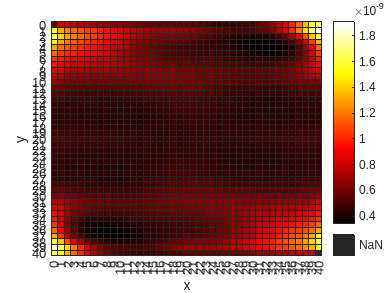

figure;
heatmap(xvals, yvals, Z)
xlabel('x')
ylabel('y')
colormap('hot');

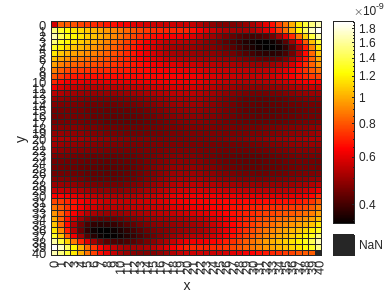

%clim([-0.01,0.01]);
drawnow;

figure;
heatmap(xvals, yvals, Z)
xlabel('x')
ylabel('y')
colormap('hot');
set(gca, "ColorScaling","log")

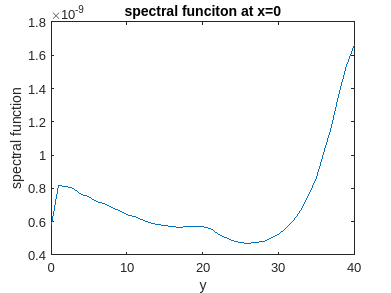

%clim([-0.01,0.01]);
drawnow;

figure;
%plot(yvals, density);
plot(yvals, Z(1,:));
xlabel('y');
ylabel('spectral function');
title('spectral funciton at x=0');

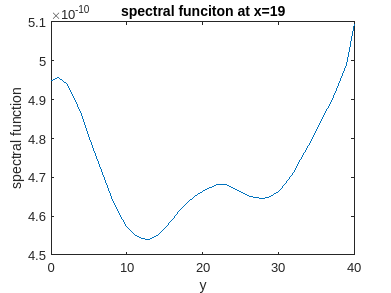

drawnow;

figure;
%plot(yvals, density);
plot(yvals, Z(floor(Nx/2),:));
xlabel('y');
ylabel('spectral function');
title(['spectral funciton at x=', num2str(xvals(floor(Nx/2)))]);

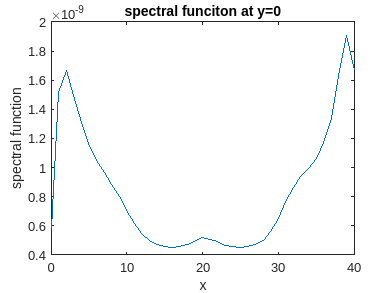

drawnow;

figure;
%plot(yvals, density);
plot(xvals, Z(:,1));
xlabel('x');
ylabel('spectral function');
title('spectral funciton at y=0');

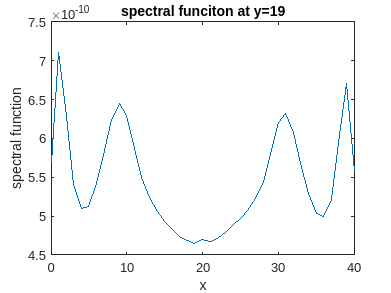

drawnow;

figure;
%plot(yvals, density);
plot(xvals, Z(:,floor(Ny/2)));
xlabel('x');
ylabel('spectral function');
title(['spectral funciton at y=', num2str(xvals(floor(Nx/2)))]);

drawnow;

function Spectralfn = Spectralfn(E, x, y, Psi, Eig, Ny)
    % Position m of x,y in eigenstate matrixes
    m = 1 + y + Ny*x;
    n = 2*m - 1;
    % Small number for spectral function
    eta = 20;
    % Construct cell array for sum in spectral function
    element = cell(1,size(Psi,1));
    for j = 1:size(Psi,1)
        element{j} = ((ctranspose(Psi(n,j)) * Psi(n,j)) / (E - real(Eig(j,j)) + 1i * eta)) + ...
        ((ctranspose(Psi(n+1,j)) * Psi(n+1,j)) / (E - real(Eig(j,j)) + 1i * eta));
    end
    Spectralfn = - imag(sum([element{:}]));
end